# View Bounding Boxes

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

load ../data/PetsImages/petGroundTruth.mat
head(petGroundTruth)

                     imageFilename                          Bengal             Chihuahua               Pug                 Samoyed              Sphynx      
    ________________________________________________    _______________    _________________    __________________    _________________    _________________

    "../data/PetsImages/Samoyed/Samoyed_175.jpg"        {0×0 double   }    {0×0 double     }    {0×0 double      }    {[215 70 72 116]}    {0×0 double     }
    "../data/PetsImages/Sphynx/Sphynx_201.jpg"          {0×0 double   }    {0×0 double     }    {0×0 double      }    {0×0 double     }    {[150 2 179 205]}
    "../data/PetsImages/Bengal/Bengal_135.jpg"          {[18 17 53 63]}    {0×0 double     }    {0×0 double      }    {0×0 double     }    {0×0 double     }
    "../da

## Task 1

At the top of the script, you can see the first few rows of the ground truth table. The images are not stored in this table. Instead, the first variable is the directory and filename of each image.

To view one of these images, you first need to extract one of the filenames.

`tableName``.``varName``{``n``}`

im = imread(petGroundTruth.imageFilename{1});

## Task 2

The remaining variables in the ground truth table are the bounding boxes for each pet.

All rows contain only one bounding box. This is because these photos contain only one animal each.

You can extract a bounding box using the same pattern as the filenames. The variable name will be the name of the label you want to extract.

You should still use brackets (`{}`) to extract the bounding box. Because there are multiple values stored in one table entry, the bounding box is stored in a cell.

`b` `=` `groundTruth``.``Label``(``1``)`

`{``1``x4` `double``}`

`b` `=` `groundTruth``.``Label``{``1``}`

`65` `150` `100` `78`

bbox = petGroundTruth.Samoyed{1};

## Task 3

When you display a bounding box on an image, you need the box's coordinates and a text label.

annotationLabel = "Samoyed";

## Task 4

To view the image along with its label, you can add the bounding box to the image.

`alteredImg` `=` `insertObjectAnnotation``(``image``,``...`

`"rectangle"``,``bbox``,``label``)`

The second input is `"rectangle"` because you are adding a rectangular bounding box to the image.

labeledim = insertObjectAnnotation(im, "rectangle", bbox, annotationLabel);

## Task 5

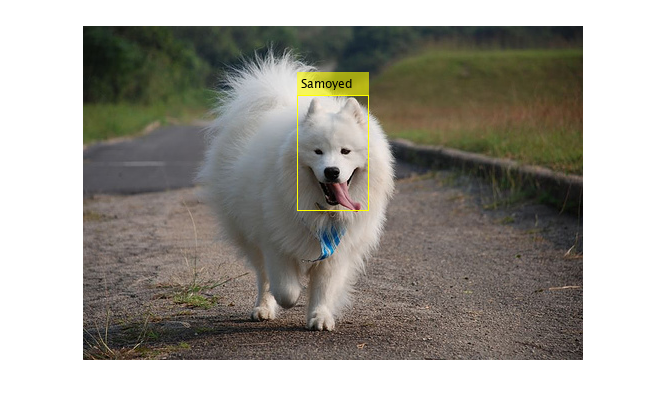

imshow(labeledim)